# Using ADI Precision Converter Toolbox System Objects

We now look at how the Precision Converter Toolbox system objects can be configured and used to stream data to and from a supported radio. Using ADALM-PLUTO as an illustrative example, we first start with describing the skeleton of any MATLAB script that interfaces with one of the supported devices or evaluation boards listed on the Supported Hardware page. This is followed by specific examples for other supported hardware highlighting their commanlity with the overall framework explained using Pluto as well as explaining any unique features specific to the system objects for that device or evaluation platform. Note that if you are running the live script and not the html page generated by it, you need to have a PlutoSDR connected to your machine in order to run the code fragments shown in this page. Also, you may have noticed that each section can be run separately from the previous one. We start with an example that uses ADALM-PLUTO to stream data.

## Steps Involved in Streaming Data To/From ADI Precision Converter Products

### Step 1 - Instantiate and Configure Transmitter System Object 

We begin by instantiating the Pluto Tx system object. 

clear all;
tx = adi.Pluto.Tx;

Next, update the URI to the device's IP address. Note that while the default IP address for Pluto is `192.168.3.1`, you may simply set the `uri` property to `ip:pluto` if Pluto is connected to your local machine. You may even use the `usb` context to set the ip address by setting the uri property to `usb:x.xx.x`, where the specific context is found by using the [`iio_info`](https://wiki.analog.com/resources/tools-software/linux-software/libiio/iio_info) utility. 

tx.uri = 'ip:pluto'; % alternatively, tx.uri = 'ip:192.168.3.1';

Now, select the data source that generates the waveform transmitted. `DataSource` is set to either `DMA`, which specifies MATLAB as the source of the data, or `DDS`, which specifies the DDS on the radio hardware as the source of the data. Let's start with `DDS` as the data source. An example with `DMA` as the data source is provided at the end of this page. 

Let's also look at the related settings when you select DDS as the data source. The frequency, phase and scale of the sinusoidal waveform generated by the DDS need to be configured using the properties `DDSFrequencies`, `DDSPhases` and `DDSScales`. Each of these properties needs to be a `2xN` matrix, where, `N` is the number of channels available on the board and the number `2` is due to the fact that the DDS is a dual-tone generator. The two tones are summed up in order to generate the final output waveform. 

Let's understand how these properties need to be set in order to generate a complex-sinusoidal waveform. Since a complex sinusoid involves generating one sinusoidal tone for each of the I and Q components, the second row in `DDSFrequencies`, `DDSPhases` and `DDSScales` would contain zeros. Additionally, the real component needs to be 90 degrees off relative to the imaginary component. Hence, we set tx`.DDSPhases(1,1)` to `90e3`. Note that the range of tx`.DDSPhases` is `[0, 360000]` with the units expressed in millidegrees.

% generate a complex sinusoidal tone
%{
tx.DDSFrequencies = [1e5 1e5; 0 0];
tx.DDSPhases = [90e3 0; 0 0]; % expressed in millidegrees
tx.DDSScales = [1 1; 0 0];
%}

Other configurations of these properties in order to generate other types of sinusoids are shown below. Notice that when generating a dual tone waveform, the scales have been reduced. This is because a DDS scale value of `1` corresponds to `0` `dBFs`. So, adding two tones each set to a scale value of `1` will digitally overdrive the input. 

% generate a complex dual tone waveform with the real component being zero
%{
tx.DDSFrequencies = [0 1e5; 0 3e5];
tx.DDSPhases = [0 0; 0 0]; % expressed in millidegrees
tx.DDSScales = [0 0.5; 0 0.5];
%}

% generate a real sinusoidal tone i.e., the imaginary component is zero
%{
tx.DDSFrequencies = [1e5 0; 0 0];
tx.DDSPhases = [0 0; 0 0]; % expressed in millidegrees
tx.DDSScales = [1 0; 0 0];
%}

% generate a complex sinusoidal tone with the real component being zero
%{
tx.DDSFrequencies = [0 1e5; 0 0];
tx.DDSPhases = [0 0; 0 0]; % expressed in millidegrees
tx.DDSScales = [0 1; 0 0];
%}

For the purpose of this example, we will consider transmitting a real dual tone waveform. 

% generate a real dual tone waveform i.e., the imaginary component is zero
tx.DataSource = 'DDS';
tx.DDSFrequencies = [1e5 0; 2e5 0];
tx.DDSPhases = [0 0; 0 0]; % expressed in millidegrees
tx.DDSScales = [0.5 0; 0.5 0];

The remaining properties of tx system object are straightforward.

tx.AttenuationChannel0 = -15;
tx.CenterFrequency = 2.44e9;
tx.SamplingRate = 5e6;
tx.RFBandwidth = 5e6;

### Step 2 - Run the Transmitter Object 

Next, run the transmitter object to transmit the DDS generated waveform continuously. 

tx();

In order to observe the waveform generated by the DDS, we connect the transmit and receive ports using an SMA cable in RF loopback mode and configure the Pluto receiver system object. Please make sure that the `AttenuationChannel0` property of tx object doesn't exceed `-10` in order to protect the RF front end. 

### Step 3 - Instantiate and Configure Receiver System Object 

Continuing from our previous discussion, we next instantiate the Pluto receiver system object, update `uri` and configure the receiver AGC in slow attack mode. We also need to ensure that the `CenterFrequency` of the `tx` and `rx` system objects are matched.  

rx = adi.Pluto.Rx('uri','ip:pluto','GainControlModeChannel0','slow_attack');
rx.CenterFrequency = tx.CenterFrequency;

Additionally, set the number of kernel buffers to `1`. For more details on the kernel buffers setup by the `iiod` running on Pluto, see [here](https://wiki.analog.com/resources/tools-software/linux-software/libiio_internals#reading_and_writing). 

rx.kernelBuffersCount = 1; 
% rx.LoopbackMode = 1; 

***NOTE*** - In the code fragment shown above, setting the `LoopbackMode` property to 1 enables digital loopback mode and bypasses the RF hardware, a useful feature for debugging purposes. You might prefer to observe the received samples by enabling digital loopback as explained shortly. 

### Step 4 - Run the Receiver Object 

Next, run the receiver object to pull in a buffer of samples from the radio. 

pause(1);
y = rx();

You will notice that `y` is a `32768` element complex double column vector passed to MATLAB from `iiod`. Let us now plot a snapshot of the time-series data. 

figure(1); 
plot(0:2^15-1, real(y), 'r', 0:2^15-1, imag(y), 'b'); 
xlim([0 250]); 
xlabel('sample index'); 
grid on;

As you can see from this plot, even though the imaginary part of the transmitted waveform was zero, the imaginary part of the received waveform is not. This is due to the loopback time delay that the waveform undergoes over the cable connecting the Tx and Rx ports of Pluto. This time delay manifests as a phase offset by the down-conversion process that converts a real passband waveform to a complex baseband waveform. On the other hand, if you were to enable digital loopback as mentioned previously, you would observe the expected waveform where the imaginary component is zero. However, doing so bypasses the RF section entirely. 

We can confirm that the waveform transmitted by the DDS is indeed a two tone waveform by observing the FFT of the received waveform. 

NFFT = 2048;
Y = fftshift(fft(y, NFFT));
delta_f = rx.SamplingRate/NFFT;
f = -rx.SamplingRate/2:delta_f:rx.SamplingRate/2-delta_f;
figure(2); 
plot(f*1e-6, 10*log10(abs(Y))); 
xlabel('frequency (MHz)');
grid on; 

While most of the properties in the `rx` system object might seem straightforward, the properties `kernelBuffersCount` and `SamplesPerFrame` need a brief explanation for completeness. When the `rx` operator is called for the first time, the kernel buffers are created within the DMA on Pluto itself. Their default number is four, are arranged as a circular buffer and they begin to be filled when the operator is called. Once the first buffer is full, it is returned and the remaining ones will continue to fill. As soon as one is requested, it frees up space for the next one. Therefore, the first four buffers are guaranteed to be contiguous. If buffers are not requested/pulled fast enough, data can be dropped between buffers after the first four. The maximum number of samples that can be captured with each buffer is `2^20`. A general rule is to set the buffer size large if the sample rate is higher, in order to keep up with the device.

Let us now see a demonstration of the discontiguous nature of samples between buffer pulls.

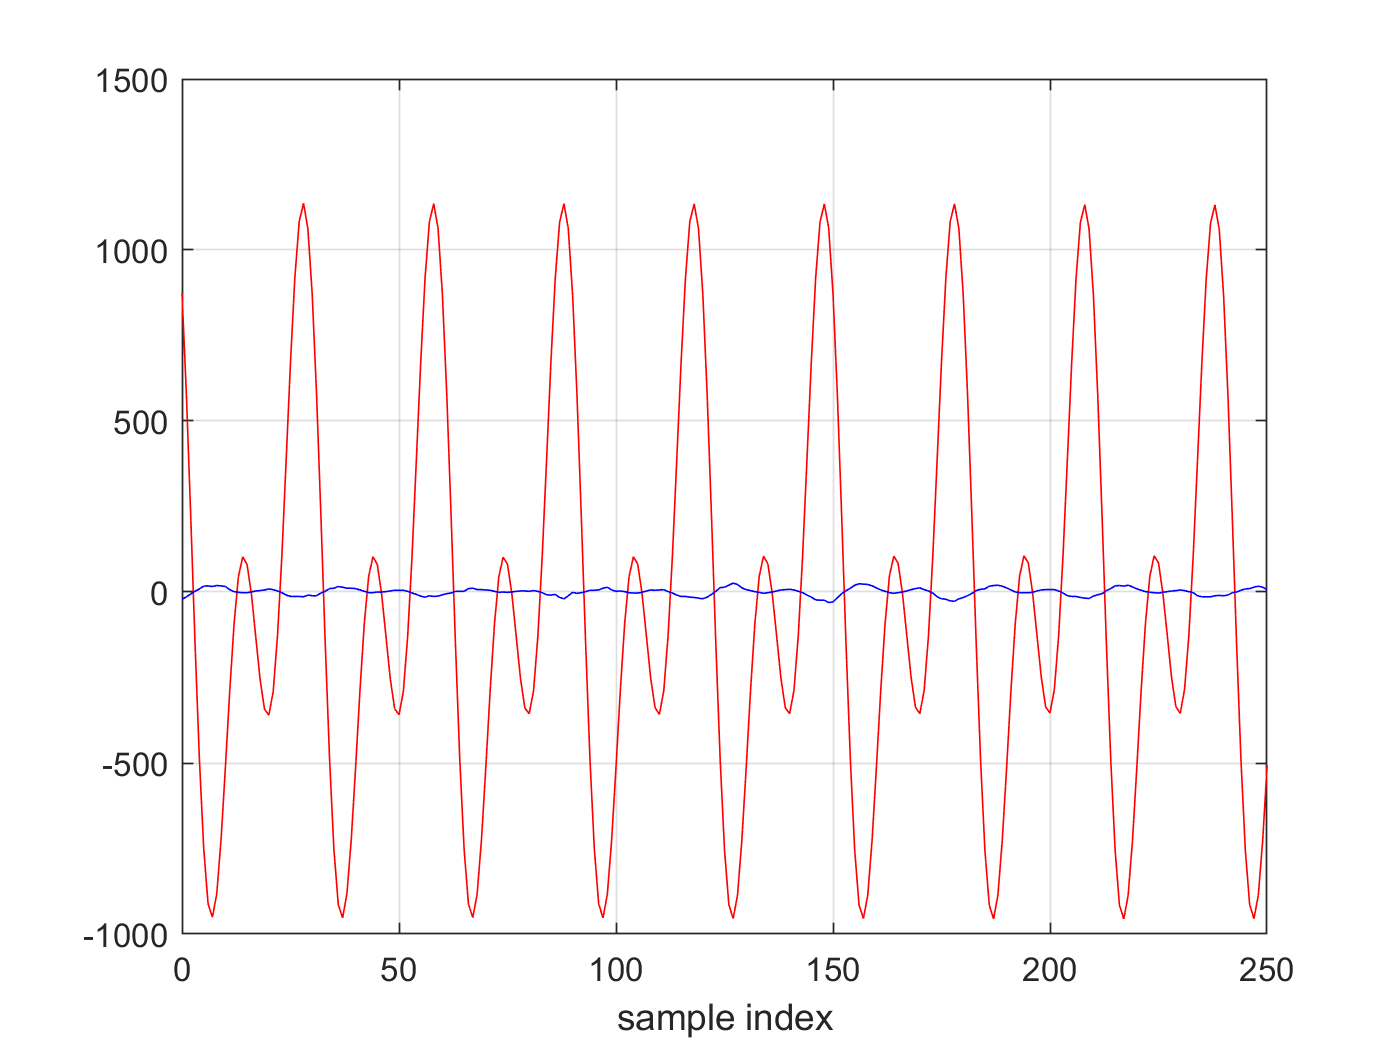

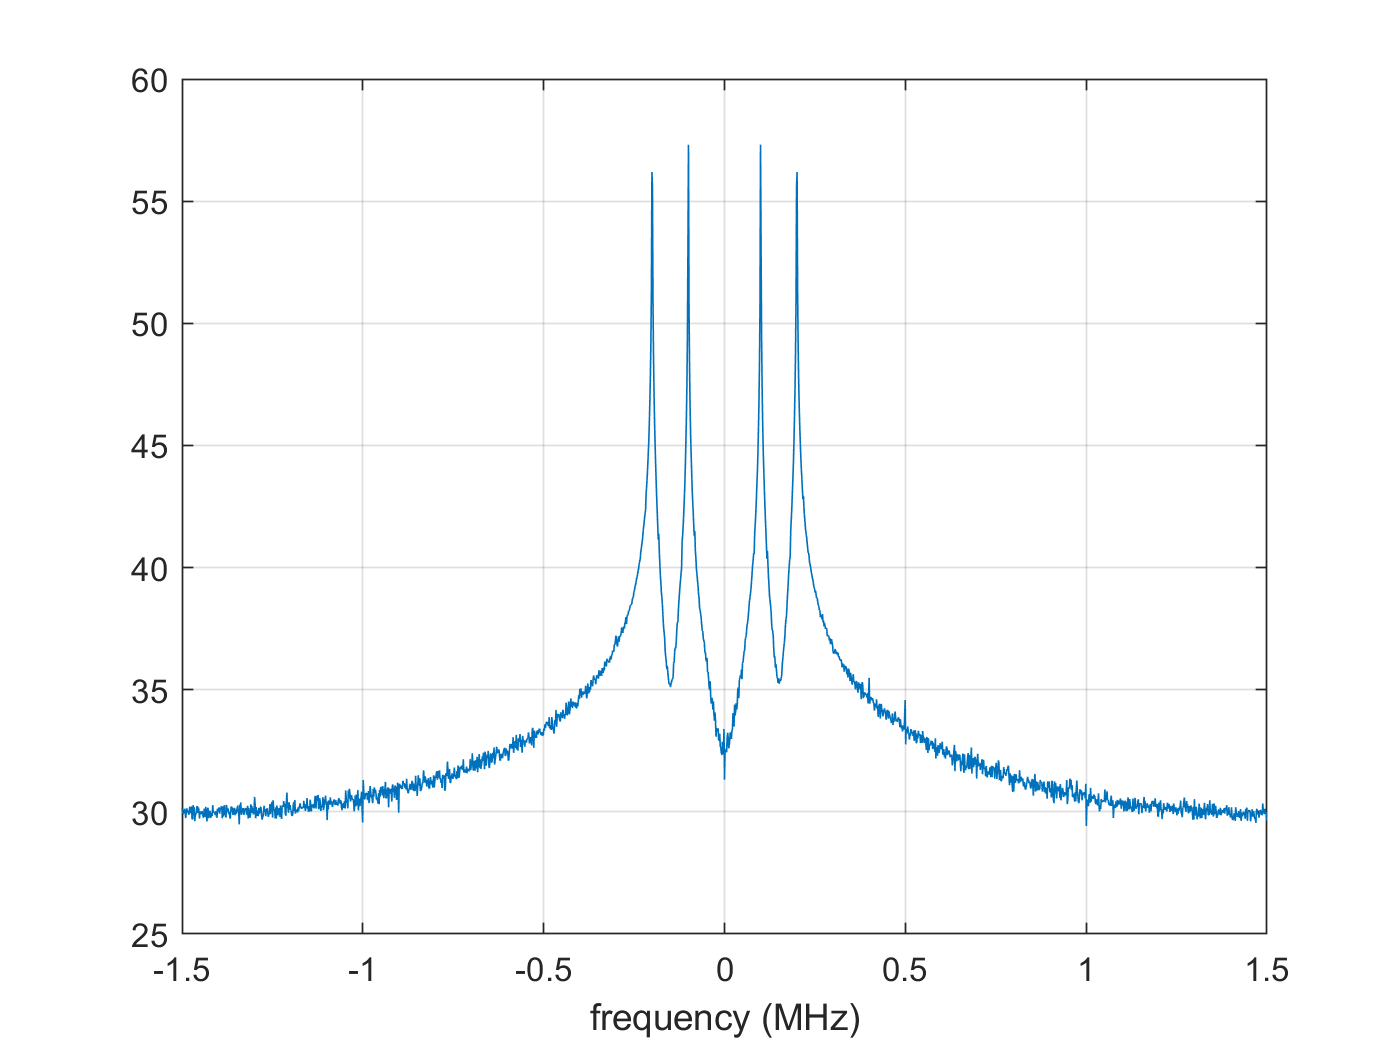

pause(5);

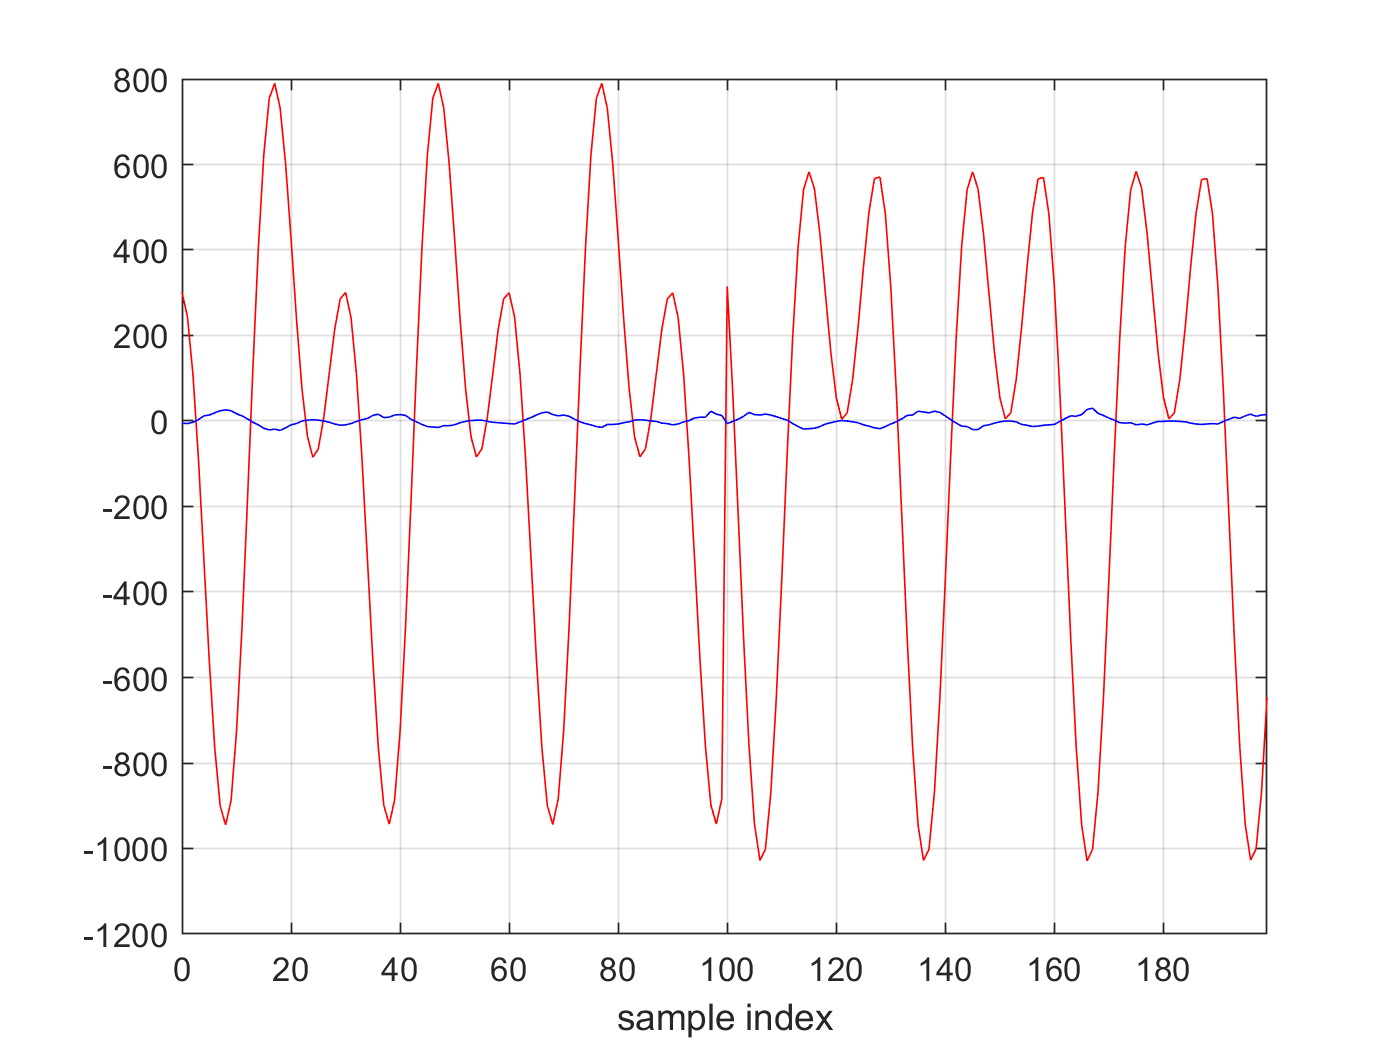

z = rx();
figure(3); 

plot(0:199, real([y(end-99:end); z(1:100)]), 'r', 0:199, imag([y(end-99:end); z(1:100)]), 'b'); 
xlim([0 199]); 
xlabel('sample index'); 
grid on;

As you can see from the previous code fragment and the associated figure, there is a discontinuity between the last 100 samples of a buffer capture and the first 100 samples of the subsequent buffer capture. However, note that the *subsequent* buffer capture does not contain the next temporally continuous set of samples. This is due to the delay that any signal processing performed between buffer captures might introduce as abstracted by the `pause(5)` command which will cause those in-between samples to be dropped by the radio.  

It is possible that when you run this experiment on your machine, you will not be able to observe a complex sinusoid in the previous two figures. This is because, any interaction with the radio is bound to be asynchronous since the communication is over USB. Depending on contention, the OS etc., the calls to the transmit and receive system objects need not occur in the order they appear in a MATLAB script. One way to reduce this possibility is to increase the time between transmit and receive calls. The `pause(1)` command prior to calling the rx operator is intended to serve this purpose. Another way is to keep polling the buffers until the first valid buffer is received. 

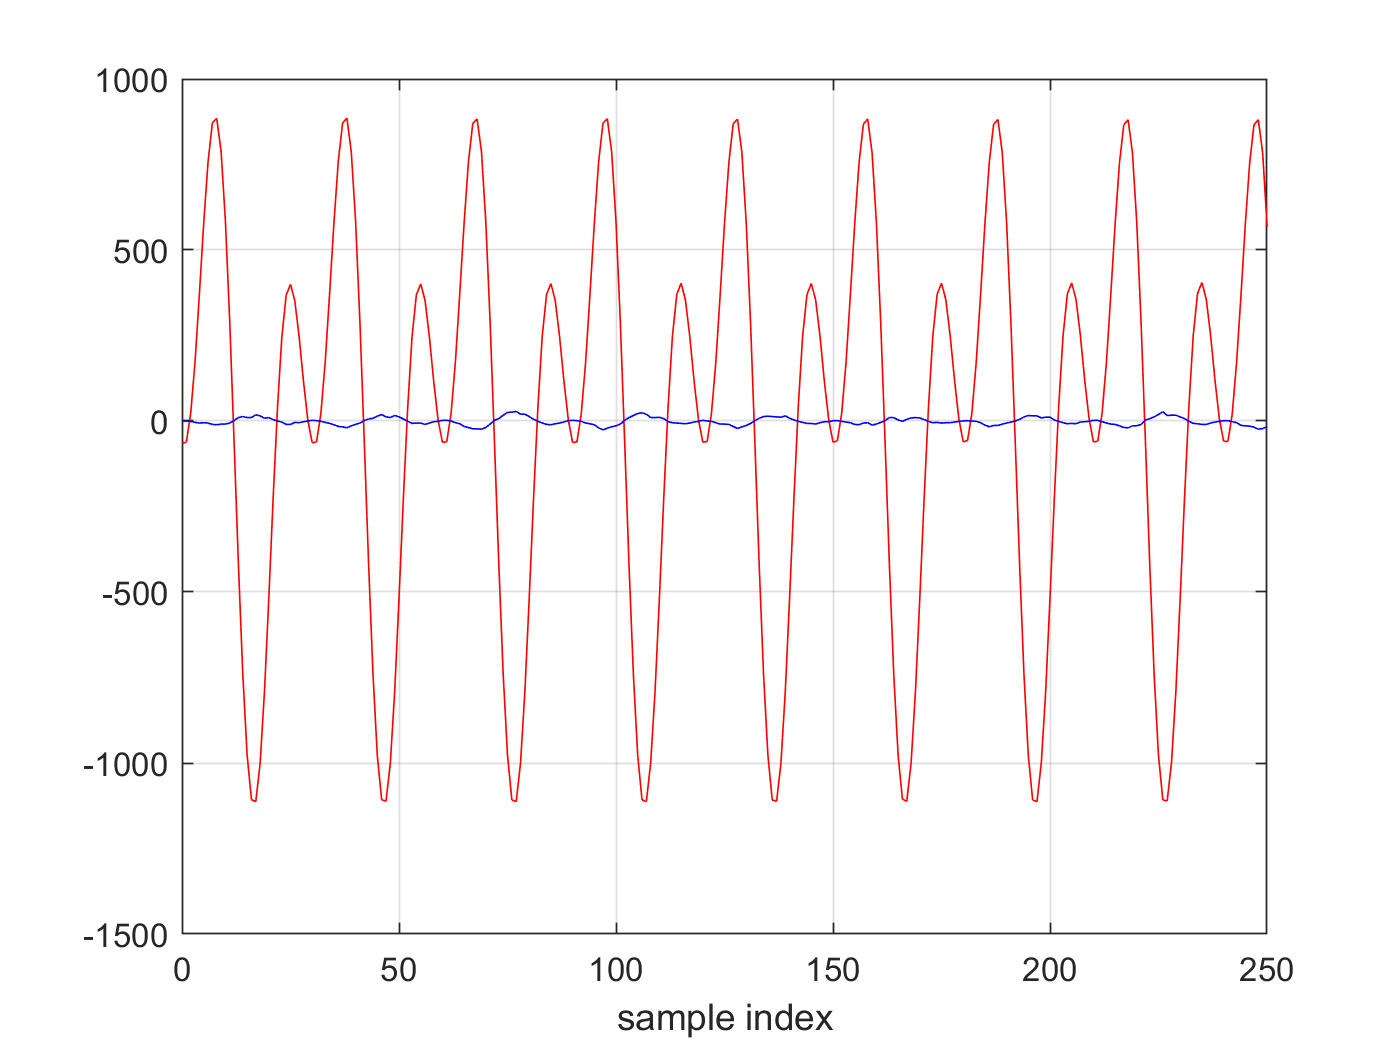

for n = 1:20
    valid = false;
    while ~valid
        [y, valid] = rx();
    end
end
figure(4); 

plot(0:2^15-1, real(y), 'r', 0:2^15-1, imag(y), 'b'); 
xlim([0 250]); 
xlabel('sample index'); 
grid on;
release(tx);
release(rx);

Finally, the release methods destroy all buffers and you reconnect to the device and redesign the programmable filters when the operators for the system objects are called next time.

## Minimal Examples for Other Supported Hardware

- Pluto (DataSource set to [DDS](matlab:open('..\..\trx_examples\streaming\ad936x\Pluto_DDS_Example.m')); DataSource set to [DMA](matlab:open('..\..\trx_examples\streaming\ad936x\Pluto_DMA_Example.m')))

- ADI RF-SOM (DataSource set to [DDS](matlab:open('./ADIRFSOM_DDS_Example.m')); DataSource set to [DMA](matlab:open('./ADIRFSOM_DMA_Example.m')))

- AD9371 (DataSource set to [DDS](matlab:open('..\..\trx_examples\streaming\ad9371\AD9371_DDS_Example.m')); DataSource set to [DMA;](matlab:open('..\..\trx_examples\streaming\ad9371\AD9371_DMA_Example.m')) [MIMO](matlab:open('..\..\trx_examples\streaming\ad9371\AD9371_MIMO_Example.m')) Example)

- ADRV9002 (DataSource set to [DDS](matlab:open('..\..\trx_examples\streaming\adrv9002\ADRV9002_DDS_Example.m')); DataSource set to [DMA](matlab:open('..\..\trx_examples\streaming\adrv9002\ADRV9002_DMA_Example.m')))

- ADRV9009 (DataSource set to [DDS](matlab:open('..\..\trx_examples\streaming\adrv9009\ADRV9009_DDS_Example.m')); DataSource set to [DMA](matlab:open('..\..\trx_examples\streaming\adrv9009\ADRV9009_DMA_Example.m')); [ORx](matlab:open('..\..\trx_examples\streaming\adrv9009\ADRV9009_ORx_Example.m')) Example)

- ADRV9009ZU11EG (DataSource set to [DMA](matlab:open('..\..\trx_examples\streaming\adrv9009\ADRV9009ZU11EG_Example.m')))